clear;clc;close all
layerfolder='../data/layers/';%Route to folder with ambiental data
Dimensions = ReadLayers(layerfolder); %The 19 environmental variables for all the map

----Reading layers----
Elapsed time is 8.891911 seconds.


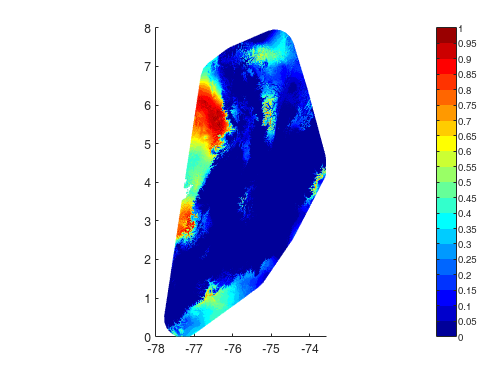

InfoInitialPoint = InitialPoint(Dimensions); %Generate a initial point to generate a niche
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true); %Generate the niche based on the initial point

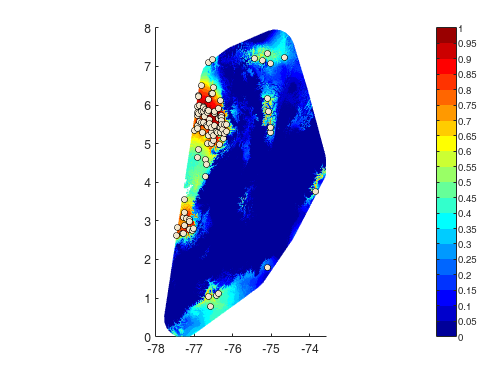

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true); %Generate samples based on the generated niche

----Finding clusters----


1 clusters identified


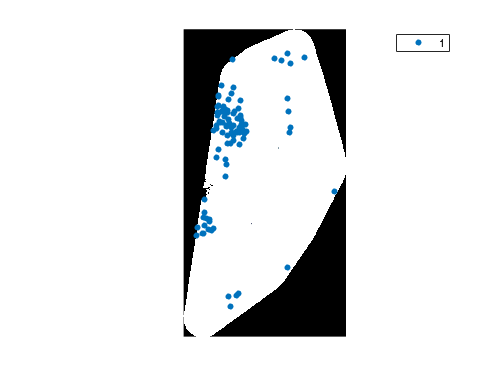

Elapsed time is 6.872376 seconds.
----Finding correlation----
Elapsed time is 11.013155 seconds.
----Creating predictors----
¡All done!
Elapsed time is 11.276572 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false); %associates the sampled data to its environmental factors

close all, clf
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers

%ColoringBorder generates classifier object with atributes nodes = environmental variables
%for each frontier point, T2 = all environmental variables for each sample,
%index = index in T2 of all frontier points, radius = distance form each
%sample to the closest frontier point and normalizers = the normalizers
%used for noramilzing new points for evaluation
class = ColoringBorder(data,0,false,outlier,outlier2); 

radius =     1.4696    2.0616    2.1133    1.8867    1.8765    2.3633    1.4714    0.8391    0.4446    1.8219    1.7154    1.8841    1.6230    1.5682    1.6433    1.6059    1.4919    1.5349    1.6867    1.6871    1.7384    1.7059    2.0098    1.8387    1.8823    1.7570    1.8215    1.7575    1.7810    1.8618    1.9425    1.7371    1.9471    1.7751    1.7420    1.7813    1.7899    2.2092    1.6378    0.8338    1.9367    1.9585    0.9627    1.8538    2.0024    0.5426    2.0789    0.4786    1.3084    0.8816
    2.0564    2.5974    2.6188    2.3403    2.3919    2.8584    2.0774    1.4462    1.0632    2.2927    2.2622    2.3903    2.1261    2.0780    2.1562    2.1402    2.0962    2.1442    2.2365    2.2037    2.2620    2.2498    2.4772    2.3567    2.4380    2.3077    2.3829    2.3091    2.2779    2.4130    2.4660    2.2172    2.4644    2.3275    2.3021    2.3342    2.3412    2.6618    2.2536    1.3038    2.4476    2.4803    1.4984    2.3027    2.5058    1.1162    2.5840    0.7420    1.8955

radiusClass =     0.4722    0.4838    0.5048    0.7288    0.4163    0.3115    0.2186    0.6213    0.3435    0.3828    0.4692    0.3790    0.6355    0.6765    0.6574    0.6441    0.5700    0.5793    0.5644    0.5249    0.4997    0.5734    0.4559    0.4857    0.5344    0.5688    0.5447    0.5481    0.3310    0.5201    0.3693    0.4796    0.3436    0.5916    0.6006    0.5586    0.5822    0.8488    0.5837    0.7459    0.4944    0.4268    0.7466    0.4701    0.4698    0.5120    0.4600    0.4786    0.4317    0.6242


MapMetric(MapInfo.Map,class.map,false) %accuracy of the generated colored map compared to the the original niche

ans =     0.7443  -10.3105


MapMetric(MapInfo.Map,dataf.Map,false)

ans =     0.9024    0.8718


newInfo = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true);
[dataNew,outland] = bnm_prep(newInfo, Dimensions, false, 0.7, false, false);
newPoints(dataNew{1},class)

----Modeling----


ij = 1

-Model 1


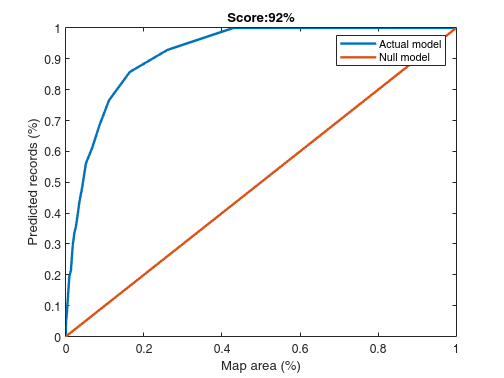

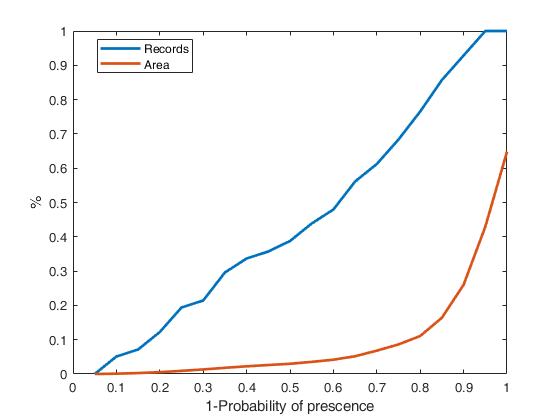

Elapsed time is 2.392404 seconds.


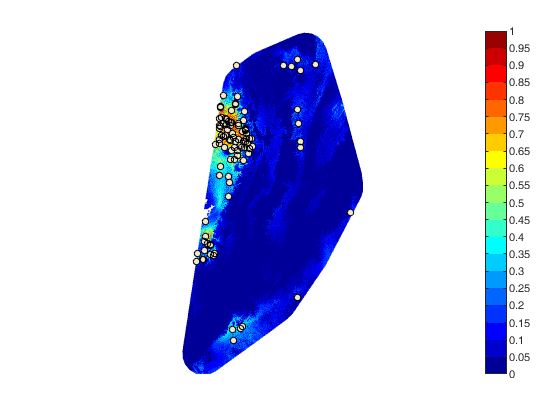

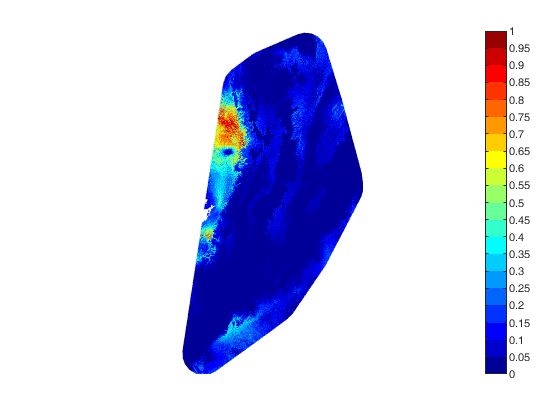

dataf = bnm_modeling(data, '', true, 4, false);

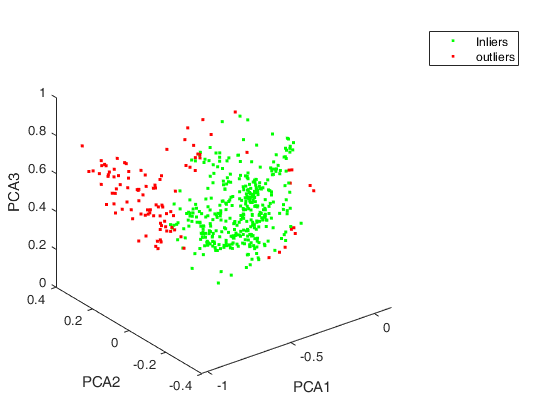

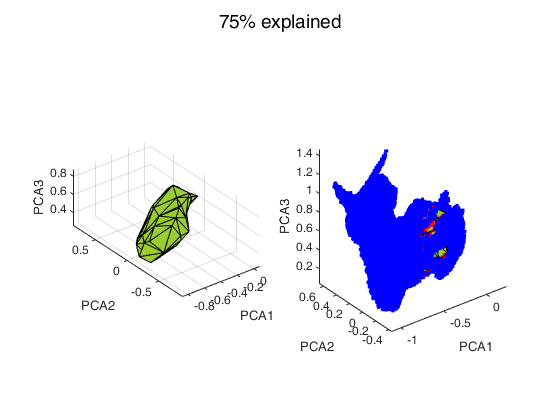

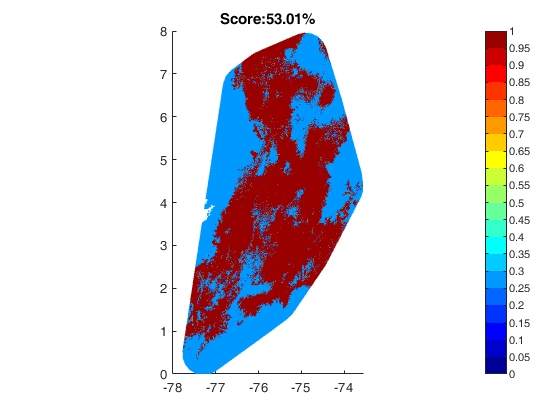

data = struct with fields:
         Tdata: [100×10 table]
    Indicators: [1 4 7 12 13 14]
          Vars: [1 4 7 12]
            T2: [493×22 table]
             Z: [956×507×19 double]
             R: [1×1 map.rasterref.GeographicCellsReference]
        MapPca: [956×507 double]
      ScorePca: 53.0071


close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)